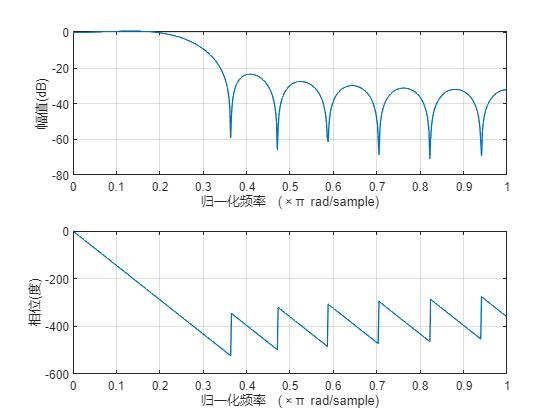

% 设计数字滤波器
fir = designfilt('lowpassfir', ...
    'PassbandFrequency',0.2,'StopbandFrequency',0.35, ...
    'PassbandRipple',1,'StopbandAttenuation',15, ...
    'DesignMethod','kaiserwin');

% 幅值和相位响应可视化
freqz(fir.Coefficients)

% fvtool(fir)
[h,t] = fir.impz;
b = fir.Coefficients;

t = 0:63;


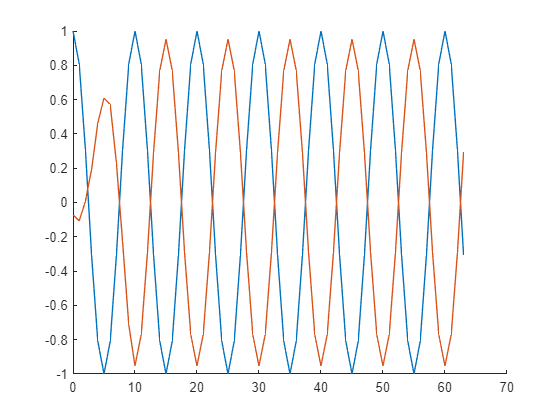

f = 0.1;
x = cos(2*pi*f*t);
y = filter(fir,x);

clf
hold on 
plot(t,x)
plot(t,y)
hold off

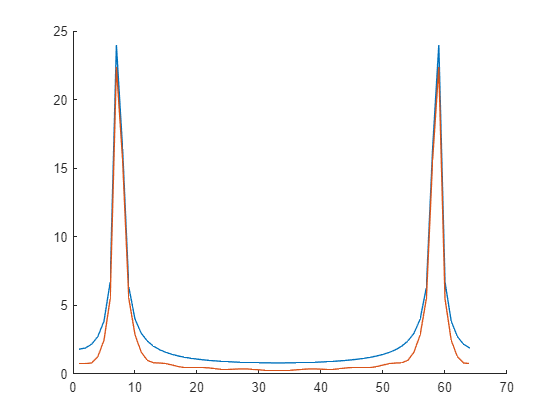


clf
hold on 
plot(abs(fft(x)))
plot(abs(fft(y)))
hold off

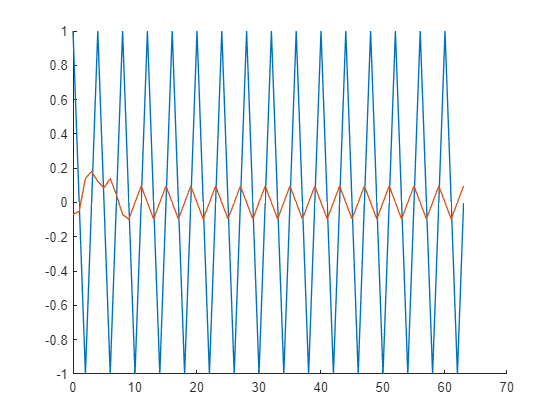

f = 0.25;
x = cos(2*pi*f*t);
y = filter(fir,x);

clf
hold on 
plot(t,x)
plot(t,y)
hold off

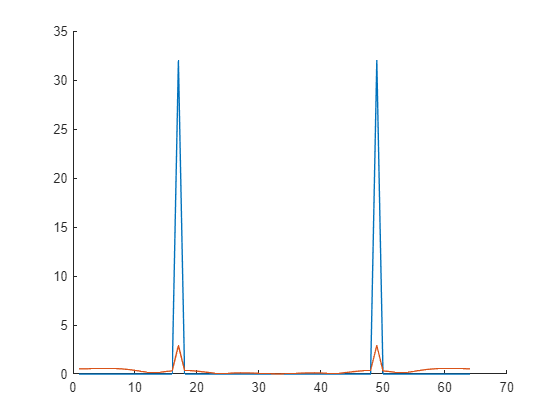


clf
hold on 
plot(abs(fft(x)))
plot(abs(fft(y)))
hold off

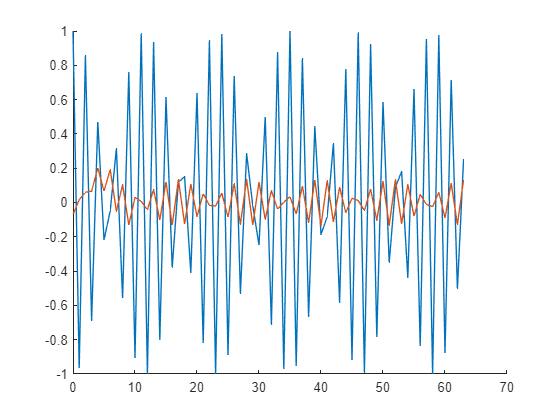

f = 0.543;
x = cos(2*pi*f*t);
y = filter(fir,x);

clf
hold on 
plot(t,x)
plot(t,y)
hold off

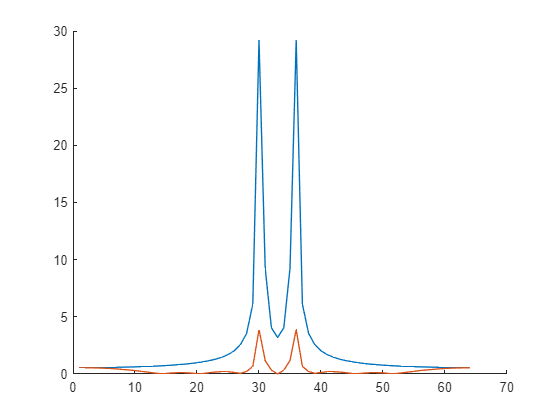


clf
hold on 
plot(abs(fft(x)))
plot(abs(fft(y)))
hold off